# Simple BLDC motor model

This is a simple brushless DC motor model. It has been written with the purpose of generate approximate motor performance charts given a few characteristics numbers and the operating voltage. Often manufacturers of small brushless motors, like those installed on flying model aircraft, do not provide performance charts, but only a few parameters together with two or three propeller as typical installation. If you want to match another torque load, say a propeller with different diameter and/or RPM, you may not know if the motor is suited for your application. As end-user looking for quick and useful info for motor-propeller coupling, you should have a tool to get the motor's steady state performance data with just the basic parameters provided by the manufacturer.

Therefore, the model here provided needs only the following inputs:

- operating voltage $V$, chosen by the user

- the $K_v$ constant, in RPM/Volt

- the no-load current $I_0$, in Ampere

- the internal resistance $R_m$, in Ohm

## The mathematical model in detail

The model is based on a power balance:


$$P_\text{electric} - P_\text{copper} - P_\text{no-load} = P_\text{shaft}$$


that is, the shaft power, i.e., the power moving the load (propeller) on the shaft, is equal to the motor electric power minus the copper and the no-load losses. The copper losses are due to the heat wasted by the internal resistance of the windings (Ohm's law). The no-load losses are due to the no-load current, i.e., the current circulating in the motor without an applied load on the shaft.

The electric power is simply the input voltage times the current absorbed by the motor:

    
$$P_\text{electric} = VI$$


The copper losses are given by the internal resistance times the square of the motor current:

    
$$P_\text{copper} = R_m I^2$$


The no-load losses are evaluated as the voltage applied to the motor times the no-load current:

    
$$P_\text{no-load} = VI_0$$


Usually the manufacturer issues the no-load current at a given voltage. However, the no-load current scales with the square root of the voltage, so that:

    
$$I_0 = I_{0,\text{ref}} \sqrt{\frac{V}{V_\text{ref}}}$$


where the subscript "ref" refers to the values issued by the manufacturer. Also, the propulsive chain is assumed to work as the following schematics.

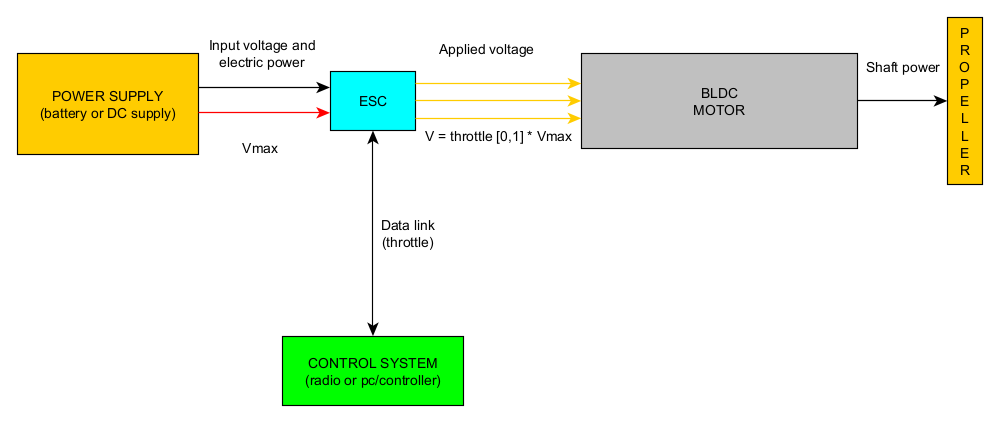

The electric power is supplied to the Electronic Speed Controller (ESC) and it is assumed constant throghout the entire operation (input voltage). The ESC provides alternate currents to the motor, but in this simple model there is the assumption that the voltage applied to the motor is the voltage provided by the power supply scaled by the throttle value *φ* from 0 to 1:

    
$$V = \varphi V_\text{max}$$


In absence of a throttle value, it is assumed that the motor is rotating at the maximum possible speed allowed by the input voltage (*φ *= 1).

From the above discussion the electric power and no-load losses are written as:

    
$$P_\text{electric} = V_\text{max}I$$


    
$$P_\text{no-load} = V I_{0,\text{ref}} \sqrt{ \frac{V} {V_\text{ref}} }$$


where the no-load power linearly scales with the throttle and by the no-load current, which in turns scales with the square root of the throttle and of the voltage ratio.

The shaft power, assuming a propeller as motor load, is written as:

    
$$P_\text{shaft} = Q(\omega) \,\omega$$


that is a torque $Q$, function of the angular velocity $\omega$, times the angular velocity $\omega$ itself.

In principle, the angular velocity may be calculated with the motor constant $K_v$ (in opportune units, since $\omega$ is in rad/s):

    
$$\omega_0 = K_v \, V$$


but since the applied load will increase the current absorbed by the motor reducing the useful (shaft) power, the angular speed will also reduce, hence $\omega_0 \ne \omega$. We assume this model:

    
$$\omega = K_v (V - R_mI)$$


that is the angular speed linearly decreases with the motor current. The higher is the load, the higher will be the current, and the angular speed will be lower with respect to the value achieved with the same voltage in the no-load case.

By rewriting the power balance equation leaving the no-load losses and the shaft power as known terms (constant throttle and maximum input voltage), we get:


$$V_\text{max}I - R_m I^2 - P_\text{no-load} = P_\text{shaft}$$


By rearranging the terms in the only unknown $I$ we get:


$$R_m I^2 - V_\text{max}I + P_\text{no-load} + P_\text{shaft} = 0$$


that is a quadratic equation where the physical solution is the smaller root:


$$I = \frac{V_\text{max} \pm \sqrt{V_\text{max}^2 -  4 R_m (P_\text{no-load} + P_\text{shaft})}} {2 R_m}$$


Also, the solution is physical if the discriminant is greater or equal than zero. That's why we treat $P_\text{shaft}$ as a known term: we are interested in motor performance chart, not in a single value of the applied load. Therefore, we calculate the current $I$ for an array of $P_\text{shaft}$ varying from zero to its maximum possible value, which is derived from the canceling of the discriminant:

 
$$V_\text{max}^2 -  4 R_m (P_\text{no-load} + P_\text{shaft}) = 0 \quad \longrightarrow \quad P_\text{shaft max} = \frac{V_\text{max}^2}{4 R_m} - P_\text{no-load}$$


Hence, the shaft power is varied as:


$$0 \le P_\text{shaft} < P_\text{shaft max}$$


(theoretically the shaft power could be equal to its maximum, but numerically the discretization error may give imaginary solutions, so in the MATLAB code we stop at 99.9% of this maximum value)

Once known the motor current $I$ we can calculate all the other parameters of interest, in particular the electric power, the angular speed, the motor efficiency, and the useful torque. The equations for the first two quantities have been presented before. The last two quantities are simply:

    $\text{eff} = \frac{P_\text{shaft}}{P_\text{electric}}$    and    $Q = \frac{P_\text{shaft}}{\omega}$

## The MATLAB live script

Here the user assigns the motor constants and change the operating voltage to get a live update of the charts.

The first three input fields are self-explanatory. The max current field `Imax` is not mandatory, but it is useful to limit the x-axis plot range. Therefore, the user may input the value of interest, even less that the value issued by the motor manufacturer. The voltage `V` can be quickly changed by the slider.

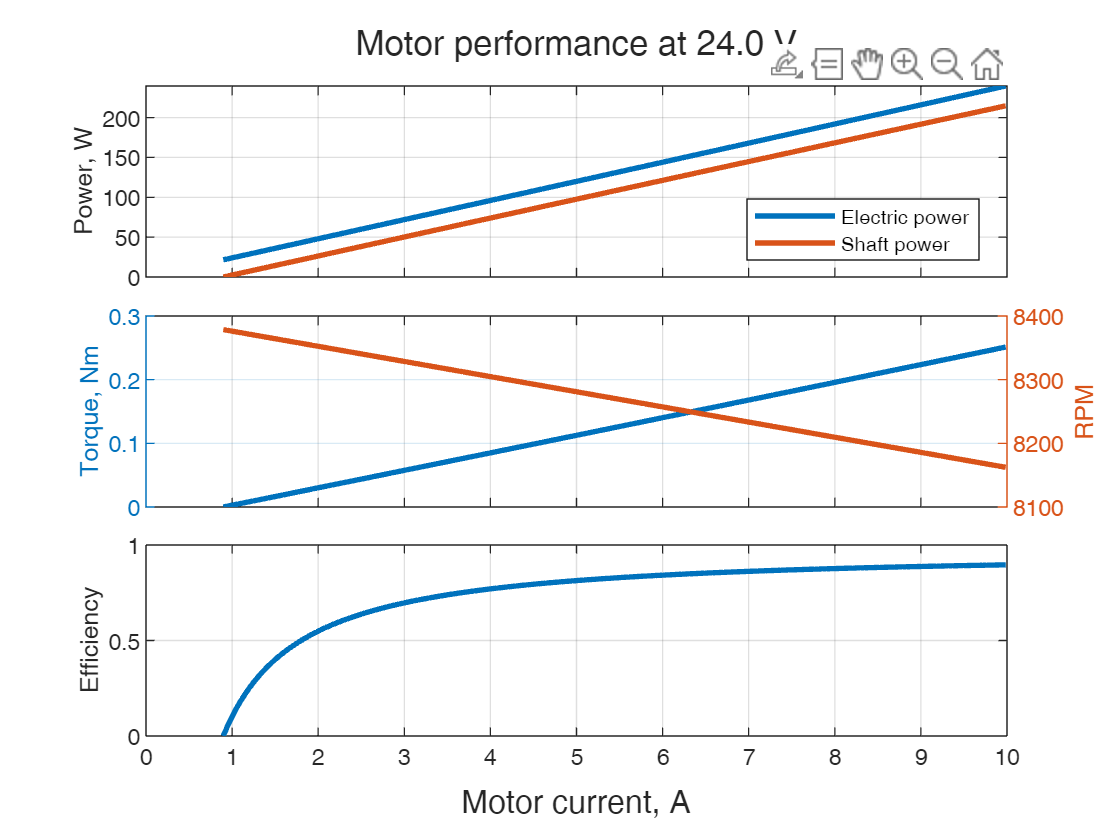

Kv = 700; % motor constant Kv, volt/RPM
I0 = 1.5; % no-load current I0, ampere
Vref = 8.4; % reference voltage for the no-load current, volt
Rm = 0.034; % motor internal resistance Rm, ohm
Imax = 10; % max current, ampere (useful to limit the axis)

V =24; % maximum voltage, volt
phi = 0.5; % throttle

[Imot, Pelec, Pshaft, Qtorque, omega, eff] = motorCalc(V,Kv,I0,Vref,Rm,phi,Imax);
RPM = omega*60/(2*pi);

t = tiledlayout(3,1);
ax1 = nexttile;
plot(Imot,Pelec,'LineWidth',2)
ylabel('Power, W')
hold on
plot(Imot,Pshaft,'LineWidth',2)
hold off
legend('Electric power','Shaft power','Location','best')
grid on

ax2 = nexttile;
yyaxis left
plot(Imot,Qtorque,'LineWidth',2)
ylabel('Torque, Nm')
%
yyaxis right
plot(Imot,RPM,'LineWidth',2)
ylabel('RPM')
ax2.YAxis(2).Exponent = 0;
% ytickformat('%.0f')
grid on


ax3 = nexttile;
plot(Imot,eff,'LineWidth',2)
grid on
ylabel('Efficiency')

linkaxes([ax1,ax2,ax3],'x');
xticklabels([ax1,ax2],{})
xlabel(t,'Motor current, A')
title(t,['Motor performance at ',num2str(V,'%.1f'),' V'])
t.TileSpacing = 'compact';

#### License

Copyright (C) 2024 Danilo Ciliberti danilo.ciliberti@unina.it

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program. If not, see <https://www.gnu.org/licenses/>